# RCS of Satellite

Create satellite surface from an STL file.

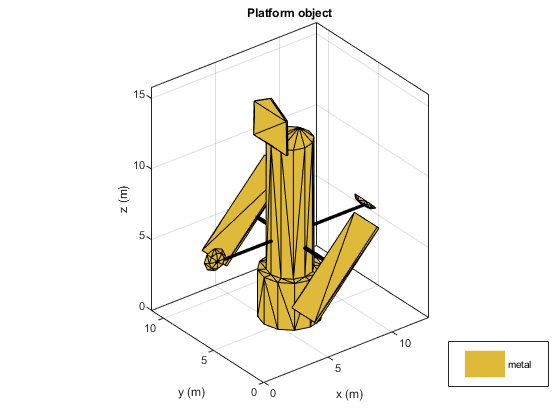

p = platform;
p.FileName = ['Satellites/hubble.stl']; 
p.Units = 'm';
freq = 450e6;
figure
show(p)

Mesh the platform with edge length of 0.5

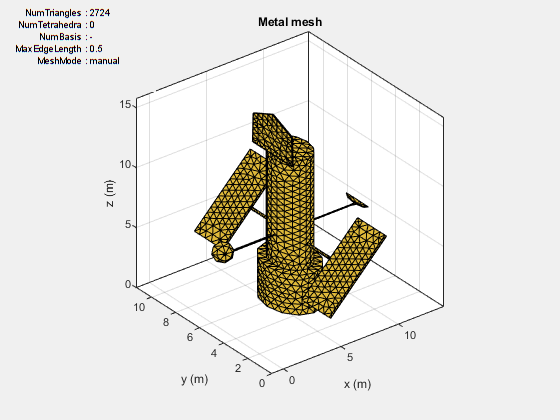

figure
mesh(p,'MaxEdgeLength', 0.5)

Sweep over the elevation with a vertically polarized E-field. Plot the RCS at 450 MHz in the azimuth plane.

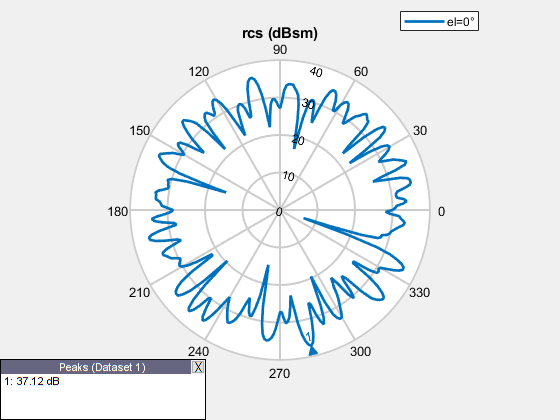

rcsval =    30.0242
   30.7297
   31.1095
   32.9046
   33.8407
   33.1832
   31.3744
   31.1780
   31.2482
   31.7263


az =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


el = 0

az = 0:1:360;
el = 0;
figure 
rcs(p,freq,az,el)
[rcsval,az,el] = rcs(p,freq,az,el)

pow = db2pow(rcsval);
pow_avg = mean(pow);
RCSavg = mean(rcsval)

RCSavg = 30.5131

RCSavgp = pow2db(pow_avg)

RCSavgp = 31.9192

*Copyright 2019 The MathWorks, Inc.*